# Laboratorium 8

### Sygnały Cyfrowe

Janusz Pawlicki

## 1. Wstęp

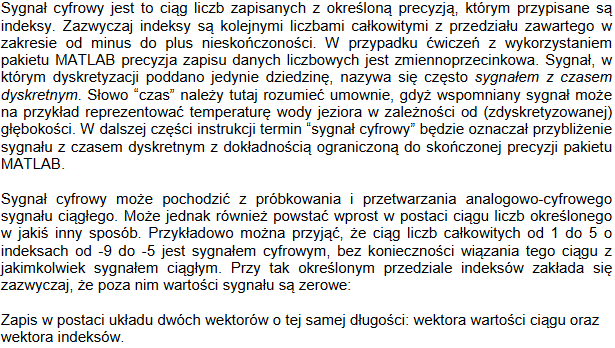

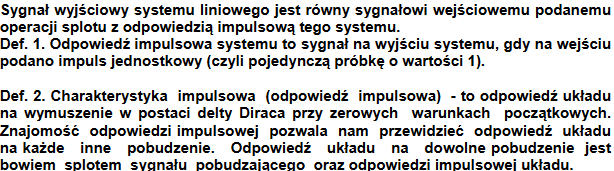

## 2. Przebieg Laboratorium

### Zadanie 2

Wygenerować i zaprezentować w postaci wykresu:

Skok jednostkowy w punkcie zero oraz przesuniętego w czasie (np. w punkcie 3),

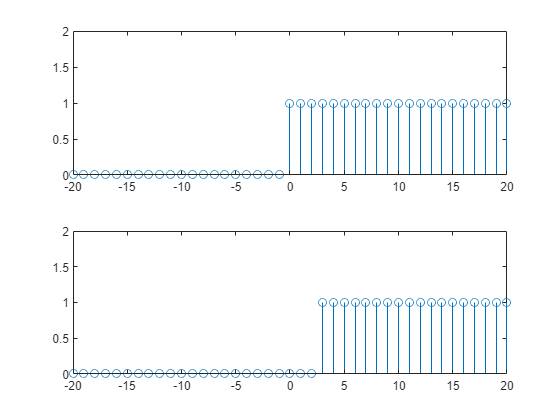

clear;
n=-20:20;
zero = 1-n(1);
x1=zeros(1,length(n));
x1(zero:end)=ones(1);
subplot(2,1,1), stem(n,x1), axis([-20 20 0 2])
k = zero + 3;
x2 = zeros(1,length(n));
x2(k:end)=ones(1);
subplot(2,1,2), stem(n,x2), axis([-20 20 0 2])

### Zadanie 3

Wygenerować i zaprezentować w postaci wykresu:

delty Kroneckera w punkcie zero oraz przesuniętej w czasie (np. w punkcie 3),

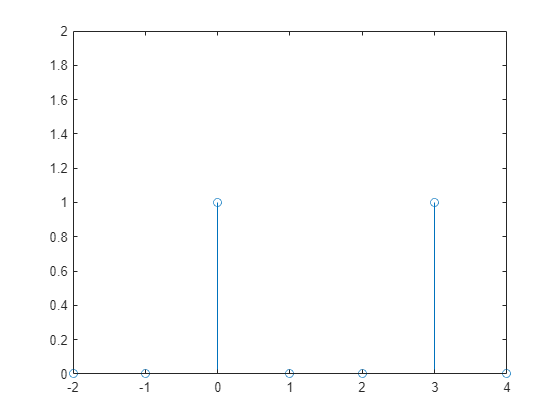

clear;
n=-2:4;
x0 = 1-n(1);
y=zeros(1,length(n));
y(x0)=ones(1);
xk = x0+3;
y(xk)=ones(1);
figure
stem(n,y), axis([-2 4 0 2])

### Zadanie 4

Wygenerować i zaprezentować w postaci wykresu: Różnicę dwóch skoków jednostkowych

(pierwszy skok jednostkowy w punkcie 0 i drugi skok jednostkowy punkcie 5).

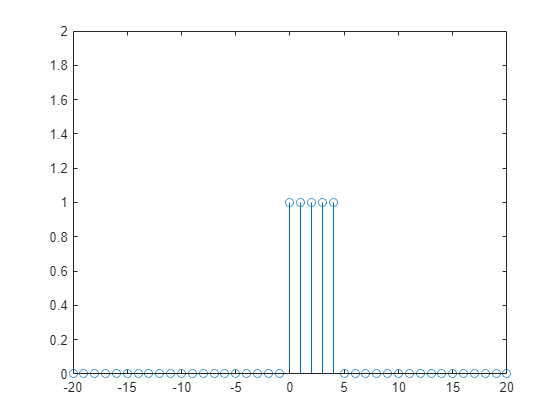

clear;
n=-20:20;
zero = 1-n(1);
x1=zeros(1,length(n));
x1(zero:end)=ones(1);
k = zero + 5;
x2 = zeros(1,length(n));
x2(k:end)=ones(1);
x = x1-x2;
figure
stem(n,x), axis([-20 20 0 2])

### Zadanie 5

Wygenerować i zaprezentować w postaci wykresu: próbkowaną sinusoidę z czasem

próbkowania `t1=0:1/10:4`; i z czasem próbkowania `t2=0:1/100:4`;

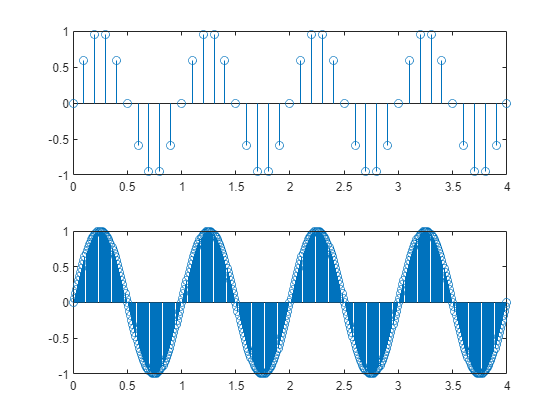

clear;
t1=0:0.1:4;
t2=0:0.01:4;
y1 = sin(2*pi*t1);
y2 = sin(2*pi*t2);
figure
subplot(2,1,1), stem(t1, y1);
subplot(2,1,2), stem(t2, y2);

### Zadanie 6

Wygenerować i zaprezentować w postaci wykresu: próbkowaną kosinusoidę z czasem

próbkowania `t1=0:1/10:4`; i z czasem próbkowania `t2=0:1/100:4;`

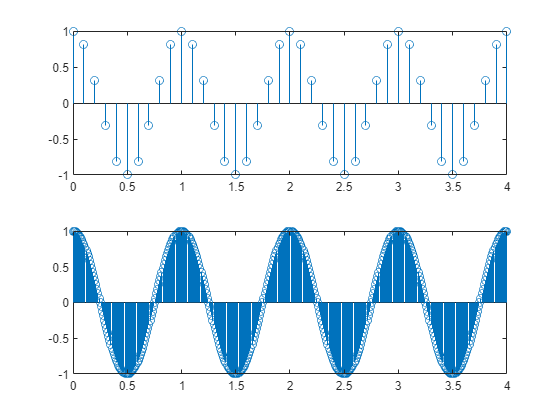

clear;
t1=0:0.1:4;
t2=0:0.01:4;
y1 = cos(2*pi*t1);
y2 = cos(2*pi*t2);
figure
subplot(2,1,1), stem(t1, y1);
subplot(2,1,2), stem(t2, y2);

### Zadanie 7

Wygenerować i zaprezentować w postaci wykresu: próbkowaną krzywą gaussa - funkcja

`gaussmf(t,[1 5])` z czasem próbkowania `t` `=` `0:0.1:10.`

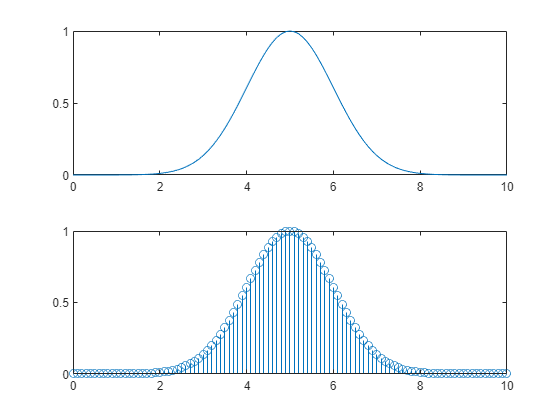

clear;
t = 0:0.1:10;
y = gaussmf(t, [1, 5]);
figure
subplot(2,1,1), plot(t, y);
subplot(2,1,2), stem(t, y);

### Zadanie 8

Proszę przemnożyć 2 sygnały `y1=[1,3,5,6,7,9,2];` `y2=[2,4,7,2,9,5,6];`

i wyrysować wynik na wykresie. Mnożenie wykonujemy przez `.*` (kropka i gwiazdka)

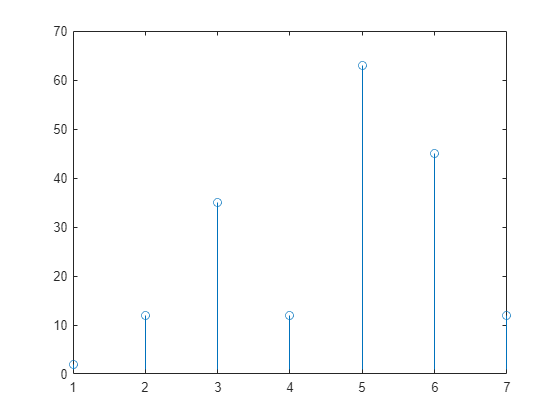

clear;
y1 = [1,3,5,6,7,9,2];
y2 = [2,4,7,2,9,5,6];
y3 = y1.*y2;
figure
stem(y3);

### Zadanie 9

Proszę narysować wykres odpowiedzi impulsowej dla n=0:20 wyrażonej następującym wzorem:

x(n)=y(n)-0.5y(n-1)+0.7y(n-2)

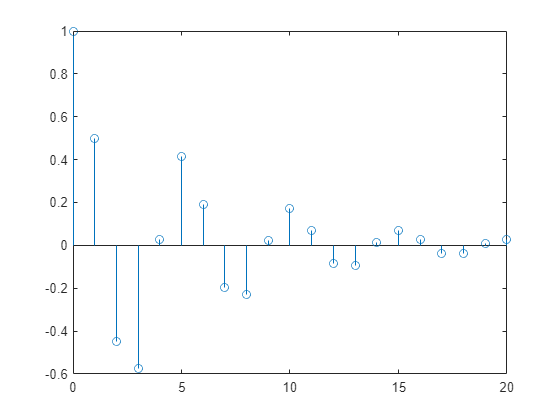

clear;
n=0:20;
x=[1,zeros(1,20)];
a=[1];
b=[1 -0.5 0.7];
y=filter(a,b,x);
figure
stem(n,y);

### Zadanie 10

Proszę wygenerować sygnał sinusoidalny z liczbą próbek n=128, t=k/128, k=0:n; Amplitudą A=1 i częstotliwością podstawową fo=2, p=0, y=A*sin((2*pi*fo*t)+p).

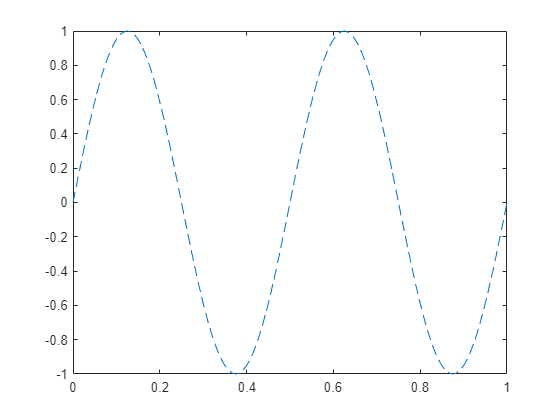

clear;
n = 128;
k = 0:n;
t = k/128;
A = 1;
fo = 2;
p = 0;
y = A*sin((2*pi*fo*t)+p);
figure
plot(t, y,'--');

### Zadanie 11

Proszę wygenerować sygnał sinusoidalny z liczbą próbek n=128, t=k/128, k=0:n; Amplitudą A=1 i częstotliwością podstawową fo=5, p=0, y=A*sin((2*pi*fo*t)+p).

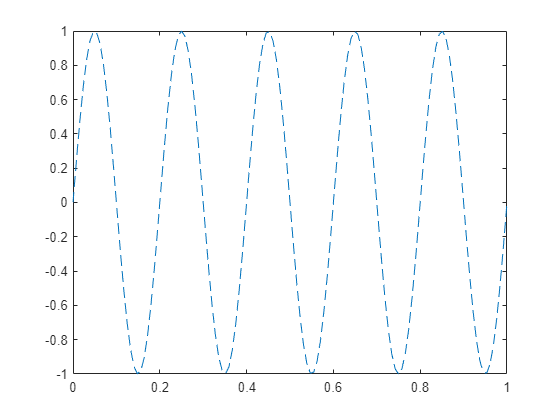

clear;
n = 128;
k = 0:n;
t = k/128;
A = 1;
fo = 5;
p = 0;
y = A*sin((2*pi*fo*t)+p);
figure
plot(t, y,'--');

### Zadanie 12

Na podstawie przykładu, wygenerować wykres pikokształtny dla częstotliwości próbkowania fs = 100.

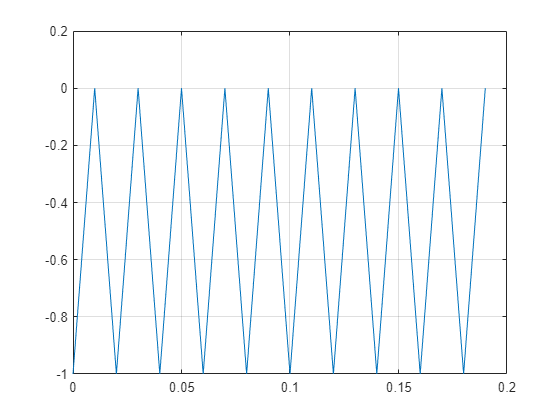

clear;
T = 10*(1/50);
fs = 100;
t = 0:1/fs:T-1/fs;
x = sawtooth(2*pi*50*t);
plot(t,x)
grid on

### Zadanie 13

Na podstawie przykładu, wygenerować wykres prostokątny dla częstotliwości próbkowania fs = 500.

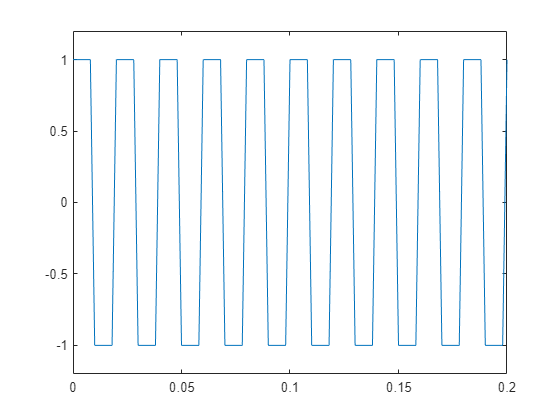

clear;
fs = 500;
t = 0:1/fs:1.5;
x = square(2*pi*50*t);
plot(t, x);
axis([0 0.2 -1.2 1.2])

### Zadanie 14

Na podstawie przykładu, wygenerować impuls trójkątny i prostokątny o szerokości 0.08.

Proszę użyć funkcji `tripuls(),` `rectpuls()`

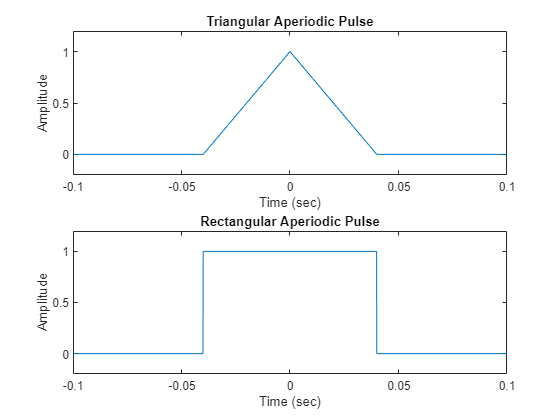

clear;
fs = 10000;
t = -1:1/fs:1;
x1 = tripuls(t,80e-3);
x2 = rectpuls(t,80e-3);
subplot(2,1,1)
plot(t,x1)
axis([-0.1 0.1 -0.2 1.2])
xlabel('Time (sec)')
ylabel('Amplitude')
title('Triangular Aperiodic Pulse')
subplot(2,1,2)
plot(t,x2)
axis([-0.1 0.1 -0.2 1.2])
xlabel('Time (sec)')
ylabel('Amplitude')
title('Rectangular Aperiodic Pulse')

### Pytania:

#### 1) W jaki sposób reprezentujemy sygnały cyfrowe na komputerze i w Matlabie?

Sygnały cyfrowe są reprezentowane w postaci wektora liczb, którego indeksy są numerami kolejnych próbek. Można je powiązać np. z dyskretnymi chwilami czasu.

#### 2) Jakie informacje może zawierać sygnał cyfrowy? Wymienić jakieś przykłady?

Sygnał cyfrowy może reprezentować właściwie dowolną mierzalną wielkość, np. temperaturę, położenie, wilgotność, natężenie światła, natężenie dźwięku, ciśnienie itd.

#### 3) Czy Pana/Pani zdaniem da się zamienić sygnały cyfrowe na sygnały analogowe?

Tak, matematycznie wykorzystuje się algorytmy interpolacji. Fizycznie zaś istnieją przetworniki cyfrowo-analogowe (C/A, DAC), które służą do zamiany sygnału cyfrowego na analogowy (najczęściej napięcie).

#### 4) Na czym polega różnica pomiędzy przekazem analogowym a cyfrowym w telewizji?

Sygnał analogowy telewizyjny (np. w formacie NTSC lub PAL) jest przesyłany w postaci zmiennego napięcia (bądź fali). Dowolne wahania tego napięcia (wywołane np. zewnętrznym polem elektromagnetycznym) powodują zakłócenia sygnału. Sygnał cyfrowy jest pozbawiony tej wady, niewielkie wahania napięcia nie mają wpływu na jego jakość. Ponadto istnieją metody weryfikacji poprawności przekazu (sumy kontrolne).

#### 5) Czy sygnał cyfrowy może mieć wiele wymiarów?

Tak, może być wielo wymiarowe, np w postaci macierzy, albo wielowymiarowy zawierające wielewymiarów.

#### 6) Czy częstotliwość próbkowania jest ważna?

Tak,im więcej próbek  zostanie pobranych (czyli im większa będzie częstotliwość próbkowania),  tym dokładniej końcowy plik cyfrowy odwzoruje oryginał. Wyższa częstotliwość próbkowania zapewnia lepszą jakość reprodukcji sygnału.